clc
clear all
close all
data=[]


data =

     []




%Parkinsons ON
"C:\Users\madav\Downloads\SIP_research\Mat-dataset"

ans = "C:\Users\madav\Downloads\SIP_research\Mat-dataset"

%PD_ON = dir('C:\Users\madav\Downloads\SIP_research\Mat-dataset\ON\*.mat')
%for i=1:24
 %   data=[data [data_extract_DMD(PD_ON(i),5);1]];
%end
%data

%Parkinsons OFF
PD_OFF = dir('C:\Users\madav\Downloads\SIP_research\Mat-dataset\OFF\*.mat')

PD_OFF = 24×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


for i=1:24
    data=[data [data_extract_DMD(PD_OFF(i),3);2]];
end

%CTL Group
PD_CTL = dir('C:\Users\madav\Downloads\SIP_research\Mat-dataset\CTL\*.mat')

PD_CTL = 25×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


for i=1:25
    data=[data [data_extract_DMD(PD_CTL(i),3);3]];
end



%clc
%clear all
%close all
%data=load("C:\Users\madav\Downloads\SIP_research\data_dmd.mat")
%data=data.data
%data=[shuffle(data(:,1:24),2) shuffle(data(:,25:48),2) shuffle(data(:,49:73),2)]
data_train=[data(:,1:18) data(:,25:42)]

data_train =     0.9457    0.9936    0.9597    0.6460    0.9608    0.8797    0.9836    0.9982    0.9607    0.9379    0.8999    0.9840    0.9933    0.9992    0.9941    0.9625    0.9949    0.9954    0.9496    0.9975    0.9980    0.9907    0.6877    0.9985    0.9431    0.9116    0.9876    0.9675    0.9969    0.9909    0.9525    0.9923    0.8779    0.9902    0.9859    0.9982
    0.3249    0.1099   -0.2812    0.7634   -0.2773    0.4755   -0.1710   -0.0549   -0.2775   -0.3468   -0.4360   -0.1028    0.1152   -0.0401    0.1079   -0.2714    0.0994   -0.0955   -0.3077   -0.0340    0.0541    0.1357    0.7260    0.0555    0.1396    0.4110    0.1283   -0.2527   -0.0634    0.1268   -0.3044    0.1179    0.4789    0.1393   -0.1587   -0.0496
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3

data_test=[data(:,19:24) data(:,43:48)]

data_test =     0.9944    0.9952    0.9928    0.9858    0.9347    0.9567    0.9982    0.9992    0.9782    0.9999    0.9934    0.9986
   -0.1048    0.0594    0.0759    0.1680    0.3305   -0.2876   -0.0496   -0.0400    0.2079    0.0166   -0.1086    0.0338
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000



%ANN

% generate an input
X = data_train(1:end-1,:)

X =     0.9457    0.9936    0.9597    0.6460    0.9608    0.8797    0.9836    0.9982    0.9607    0.9379    0.8999    0.9840    0.9933    0.9992    0.9941    0.9625    0.9949    0.9954    0.9496    0.9975    0.9980    0.9907    0.6877    0.9985    0.9431    0.9116    0.9876    0.9675    0.9969    0.9909    0.9525    0.9923    0.8779    0.9902    0.9859    0.9982
    0.3249    0.1099   -0.2812    0.7634   -0.2773    0.4755   -0.1710   -0.0549   -0.2775   -0.3468   -0.4360   -0.1028    0.1152   -0.0401    0.1079   -0.2714    0.0994   -0.0955   -0.3077   -0.0340    0.0541    0.1357    0.7260    0.0555    0.1396    0.4110    0.1283   -0.2527   -0.0634    0.1268   -0.3044    0.1179    0.4789    0.1393   -0.1587   -0.0496


% generate an output
Y = data_train(end,:)

Y =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3



% generate an input
X_test = data_test(1:end-1,:)

X_test =     0.9944    0.9952    0.9928    0.9858    0.9347    0.9567    0.9982    0.9992    0.9782    0.9999    0.9934    0.9986
   -0.1048    0.0594    0.0759    0.1680    0.3305   -0.2876   -0.0496   -0.0400    0.2079    0.0166   -0.1086    0.0338


% generate an output
Y_test = data_test(end,:)

Y_test =      2     2     2     2     2     2     3     3     3     3     3     3


%knn
X'

ans =     0.9457    0.3249
    0.9936    0.1099
    0.9597   -0.2812
    0.6460    0.7634
    0.9608   -0.2773
    0.8797    0.4755
    0.9836   -0.1710
    0.9982   -0.0549
    0.9607   -0.2775
    0.9379   -0.3468


Y'

ans =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


Mdl_knn = fitcknn(X',Y','NumNeighbors',3,'Standardize',1);

flwrClass = predict(Mdl_knn,X_test');

sum(flwrClass==Y_test')/18

ans = 0.3333


[m,order] = confusionmat(Y_test',flwrClass)

m =      2     4
     2     4


order =      2
     3


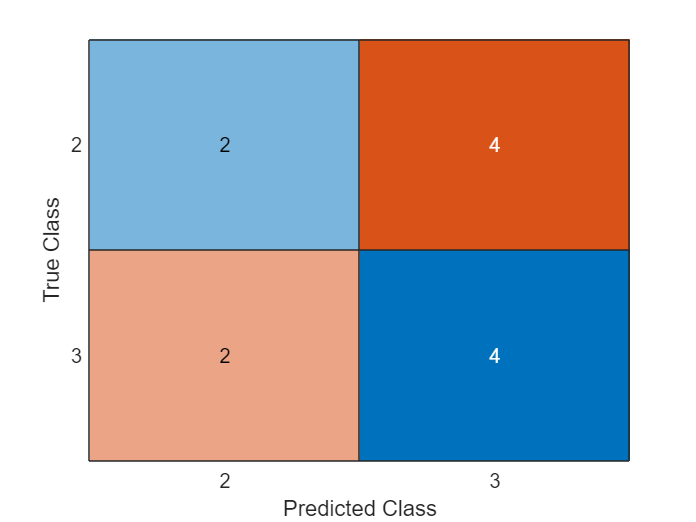

figure
cm = confusionchart(m,order);


% normalize data
[x_normalized, min_x,max_x] = normalizez(X)                                        

x_normalized =     0.8488    0.9843    0.8882         0    0.8914    0.6618    0.9560    0.9973    0.8912    0.8267    0.7191    0.9572    0.9836    1.0000    0.9856    0.8962    0.9878    0.9894    0.8598    0.9954    0.9968    0.9762    0.1182    0.9980    0.8413    0.7522    0.9673    0.9105    0.9938    0.9766    0.8680    0.9805    0.6566    0.9748    0.9625    0.9973
    0.6345    0.4552    0.1291    1.0000    0.1324    0.7600    0.2210    0.3178    0.1322    0.0744         0    0.2778    0.4596    0.3301    0.4535    0.1373    0.4464    0.2839    0.1070    0.3352    0.4086    0.4767    0.9688    0.4098    0.4800    0.7062    0.4705    0.1528    0.3107    0.4693    0.1098    0.4618    0.7628    0.4797    0.2312    0.3222


min_x =     0.6460   -0.4360


max_x =     0.9992    0.7634


[y_normalized, min_y,max_y] = normalizez(Y)

y_normalized =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


min_y = 2

max_y = 3

%TEST
[x_test_normalized, min_test_x,max_test_x] = normalizez(X_test)

x_test_normalized =     0.9167    0.9288    0.8916    0.7839         0    0.3381    0.9747    0.9897    0.6669    1.0000    0.9001    0.9800
    0.2958    0.5614    0.5880    0.7371    1.0000         0    0.3851    0.4006    0.8016    0.4922    0.2896    0.5200


min_test_x =     0.9347   -0.2876


max_test_x =     0.9999    0.3305


[y_test_normalized, min_test_y,max_test_y] = normalizez(Y_test)

y_test_normalized =      0     0     0     0     0     0     1     1     1     1     1     1


min_test_y = 2

max_test_y = 3

%Logistic regression
mdl_LR = fitglm(X',Y');

I1=predict(mdl_LR,X_test');

sum(floor(I1)==Y_test')/12

ans = 0.5000

[m,order] = confusionmat(Y_test',floor(I1))

m =      6     0
     6     0


order =      2
     3


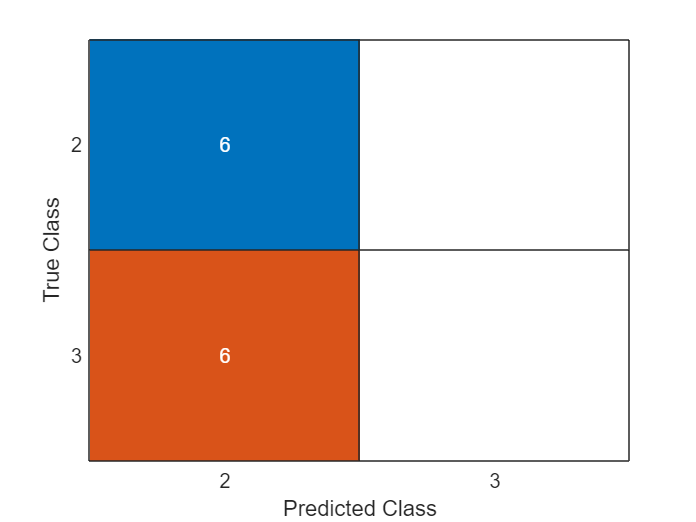

figure
cm = confusionchart(m,order);


% The column vector, species, consists of iris flowers of three different species, setosa, versicolor, virginica. The double matrix meas consists of four types of measurements on the flowers, the length and width of sepals and petals in centimeters, respectively.
% Define the nominal response variable using a categorical array.
sp = categorical(Y');
% Fit a multinomial regression model to predict the species using the measurements.  
[B,dev,stats] = mnrfit(X',Y');
sum(B*X);

[M I]=max(mnrval(B,X_test')');

sum(I==Y_test)/12

ans = 0.5833


[m,order] = confusionmat(Y_test',I)

m =      2     4
     1     5


order =      2
     3


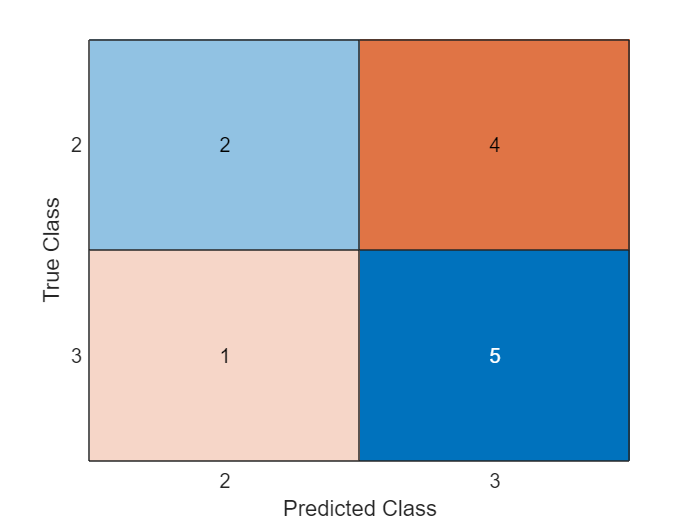

figure
cm = confusionchart(m,order);

%Descision-Tree
Mdl_DT = fitctree(X',Y');
I2=predict(Mdl_DT,X_test');
sum(I2==Y_test')/12

ans = 0.7500

[m,order] = confusionmat(Y_test',I2)

m =      4     2
     1     5


order =      2
     3


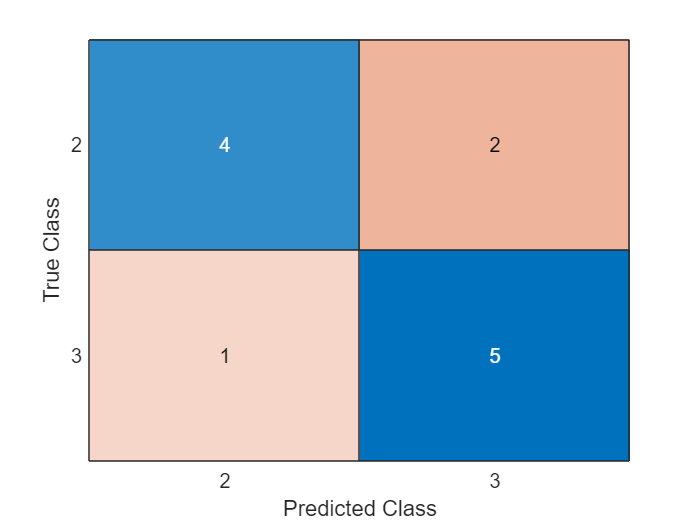

figure
cm = confusionchart(m,order);

%SVM
ivl=[1:18 37:34];
ivl_test=[1:7 14:18];
Mdl_svm = fitcsvm(X(:,:)',Y(:,:)');

I3=predict(Mdl_svm,X_test(:,:)');
Y(:,ivl)';
sum(I3==Y_test(:,:)')/12

ans = 0.4167


[m,order] = confusionmat(Y_test(:,:)',I3)

m =      4     2
     5     1


order =      2
     3


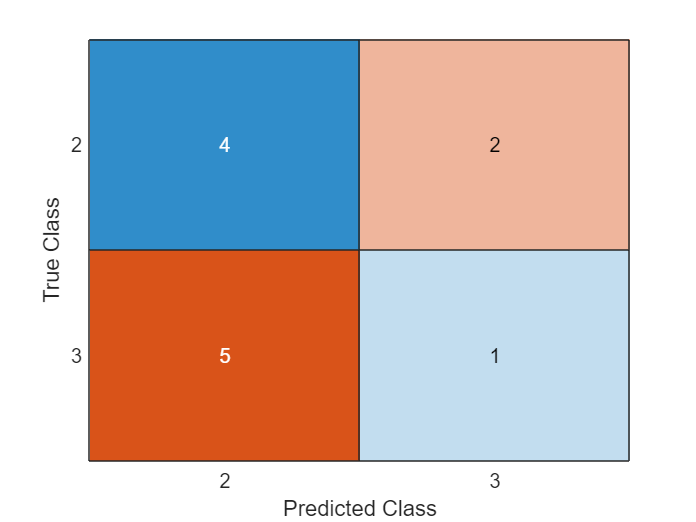

figure
cm = confusionchart(m,order);

%BAGGING

%load fisheriris
%X = meas;
%Y = species;

rng();

Mdl = TreeBagger(50,X',Y',...
    Method="classification",...
    OOBPrediction="on");


I4=cell2mat(predict(Mdl,X_test'))

I4 = 12×1 char array
    '2'
    '2'
    '2'
    '3'
    '2'
    '2'
    '3'
    '2'
    '3'
    '3'
    '2'
    '3'



sum(I4==int2str(Y_test'))/12

ans = 0.7500



[m,order] = confusionmat(int2str(Y_test'),I4)

m =      5     1
     2     4


order = 2×1 char array
    '2'
    '3'


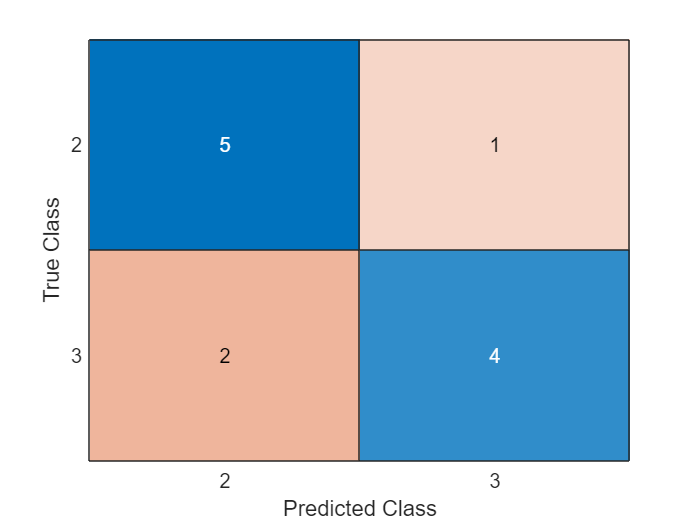

figure
cm = confusionchart(m,order);

%XG-Boost





